# your mum

## state only

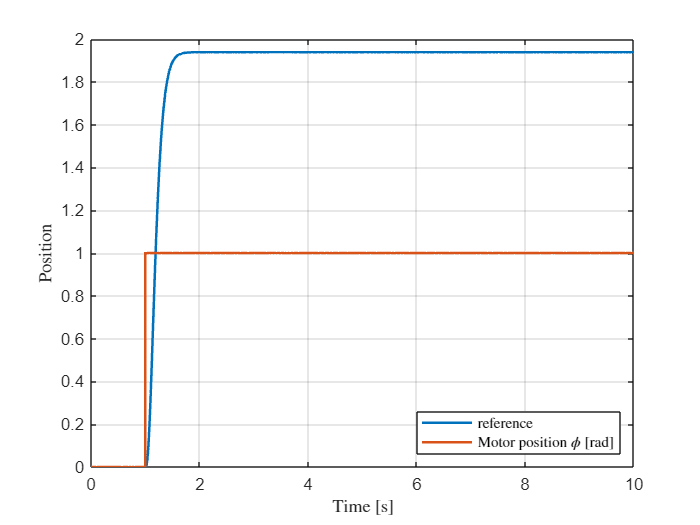


% Load the .mat file
load("stateF_resp.mat");  % Assumes the timeseries is stored as variable 'ans'

% Extract timeseries data
u_m = ans.Data(:,1);        % Motor voltage (reference)
omega_m = ans.Data(:,2);    % Motor position
time = ans.Time;            % Time vector

% Create figure
figure;
plot(time, u_m, 'LineWidth', 1.5); hold on;
plot(time, omega_m, 'LineWidth', 1.5);
ylabel('Position', 'Interpreter', 'latex');
xlabel('Time [s]', 'Interpreter', 'latex');
title('', 'Interpreter', 'latex');
grid on;

legend({'reference', 'Motor position $\phi$ [rad]'}, ...
    'Location', 'southeast', 'Interpreter', 'latex');

% Save as EPS
print('plots/phi_only_state_feedback', '-depsc');

## pid + state

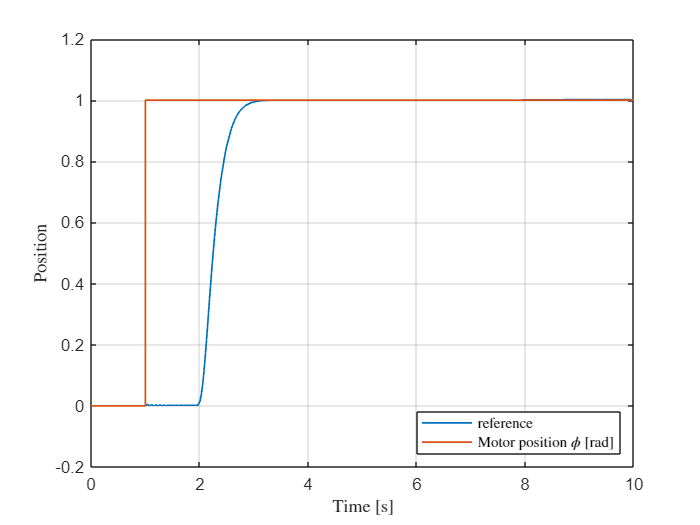

% Load the .mat file
load("stateF_pid_noComp_resp.mat");  % Assumes the timeseries is stored as variable 'ans'

% Extract timeseries data
u_m = ans.Data(:,1);        % Motor voltage (reference)
omega_m = ans.Data(:,2);    % Motor position
time = ans.Time;            % Time vector

% Create figure
figure;
plot(time, u_m, 'LineWidth', 1); hold on;
plot(time, omega_m, 'LineWidth', 1);
ylabel('Position', 'Interpreter', 'latex');
xlabel('Time [s]', 'Interpreter', 'latex');
title('', 'Interpreter', 'latex');
grid on;

legend({'reference', 'Motor position $\phi$ [rad]'}, ...
    'Location', 'southeast', 'Interpreter', 'latex');

% Save as EPS
print('plots/phi_state_feedback_pid', '-depsc');

## pid + state + comp

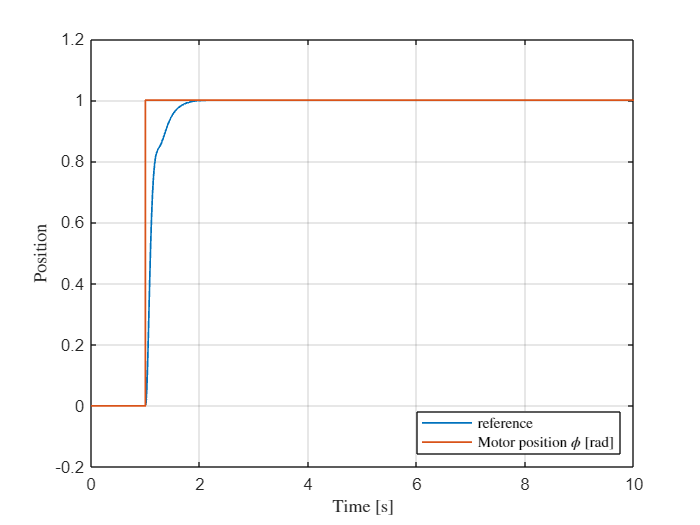

% Load the .mat file
load("stateF_pid_Comp_resp.mat");  % Assumes the timeseries is stored as variable 'ans'

% Extract timeseries data
u_m = ans.Data(:,1);        % Motor voltage (reference)
omega_m = ans.Data(:,2);    % Motor position
time = ans.Time;            % Time vector

% Create figure
figure;
plot(time, u_m, 'LineWidth', 1); hold on;
plot(time, omega_m, 'LineWidth', 1);
ylabel('Position', 'Interpreter', 'latex');
xlabel('Time [s]', 'Interpreter', 'latex');
title('', 'Interpreter', 'latex');
grid on;

legend({'reference', 'Motor position $\phi$ [rad]'}, ...
    'Location', 'southeast', 'Interpreter', 'latex');

% Save as EPS
print('plots/phi_state_feedback_pid_comp', '-depsc');

## disturbance rejetion

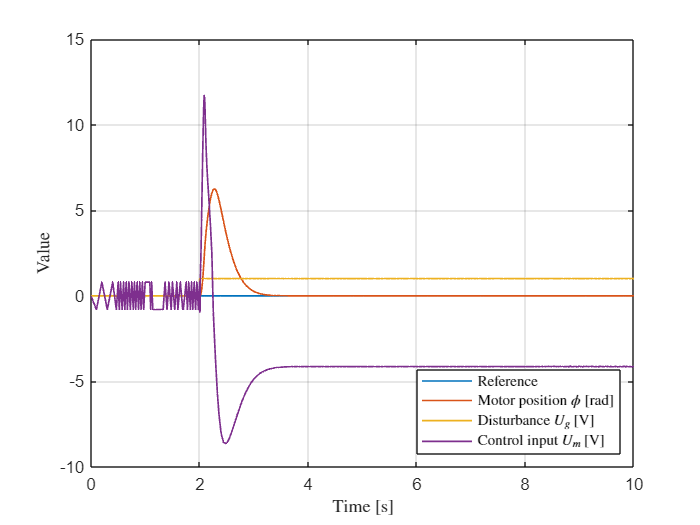

% Load the .mat file
load("stateF_pid_Comp_resp_disturbance.mat");  % Assumes the timeseries is stored as variable 'ans'

% Extract timeseries data
reference     = ans.Data(:,2);  % Reference signal
phi           = ans.Data(:,1);  % Motor position
disturbance   = ans.Data(:,4);  % Disturbance input
control_input = ans.Data(:,3);  % Control signal (u)

time = ans.Time;  % Time vector

% Create figure
figure;
plot(time, reference, 'LineWidth', 1); hold on;
plot(time, phi, 'LineWidth', 1);
plot(time, disturbance, 'LineWidth', 1);
plot(time, control_input, 'LineWidth', 1);

ylabel('Value', 'Interpreter', 'latex');
xlabel('Time [s]', 'Interpreter', 'latex');
title('', 'Interpreter', 'latex');
grid on;

legend({ ...
    'Reference', ...
    'Motor position $\phi$ [rad]', ...
    'Disturbance $U_g$ [V]', ...
    'Control input $U_m$ [V]' ...
    }, 'Location', 'southeast', 'Interpreter', 'latex');

% Save as EPS
print('plots/phi_state_feedback_pid_comp_disturbance', '-depsc');